Optimization terminated: maximum number of generations exceeded.


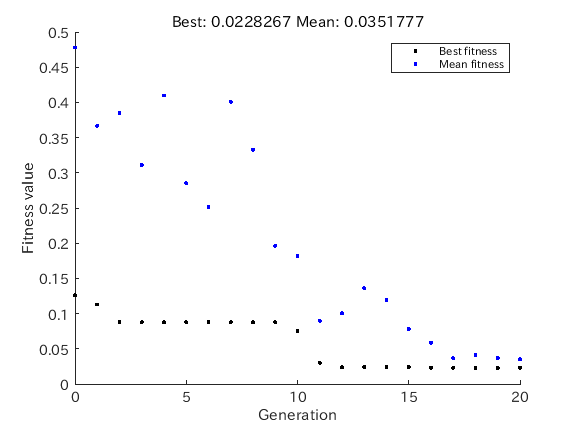

x =    4.055273471213209   2.665991539518728


F6=@(x)(0.5-((sin(x(1)^2+x(2)^2))^2-0.5)/(1.0+0.001*(x(1)^2+x(2)^2))^2);
options=gaoptimset('Generations',20,'PopulationSize',20,'PlotFcns',@gaplotbestf);
lb=[-20, -20]; % lower bound of (x1,x2)
up=[20, 20]; % upper bound of (x1,x2)
x=ga(F6,2,[],[],[],[],lb,up,[],options)